# Exercise 1

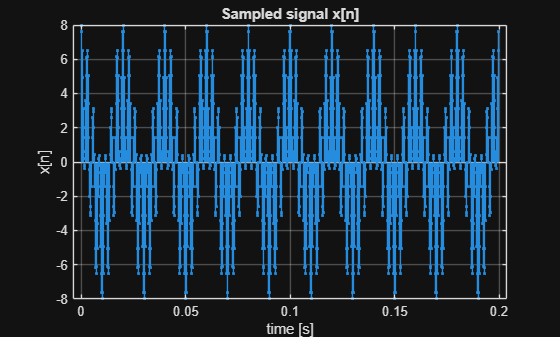


Fs = 5000;              % sampling frequency [Hz]
Ts = 1/Fs;              % sampling period [s]
N  = 1000;              % number of samples

n = 1:N;                % sample indices
t = 0:Ts:(N-1)*Ts;    % 0, Ts, 2Ts, ..., (N-1)Ts Time vector

% Signal Parameters
A1 = 4;  A2 = 4;
F1 = 50; F2 = 350;


%x(t) = A1*cos(2*pi*F1*t) + A2*cos(2*pi*F2*t);
% Sampled signal x[n]
x = A1*cos(2*pi*F1*t) + A2*cos(2*pi*F2*t);

Df = 1/(N*Ts);
f = [-Fs/2:Df:(Fs/2)-Df];

%a)
% Plot as stem vs time
figure; stem(t, x, '.'); grid on
xlabel('time [s]'); ylabel('x[n]')
title('Sampled signal x[n]')

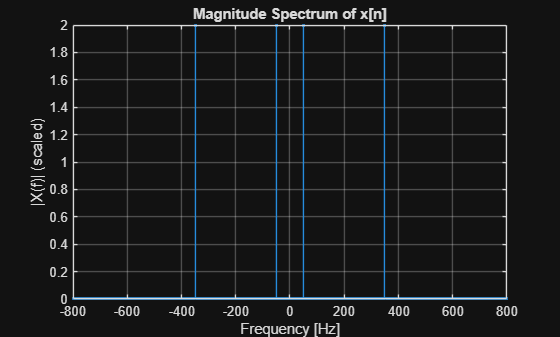


% FFT and frequency axis
X  = fft(x);            % raw FFT
Xc = fftshift(X);       % center zero freq
Xc = Xc / N;            % scale by N

Df = Fs/N;              % frequency spacing [Hz]

% Plot magnitude spectrum
figure;
stem(f, abs(Xc), '.'); grid on
xlabel('Frequency [Hz]');
ylabel('|X(f)| (scaled)');
title('Magnitude Spectrum of x[n]');
xlim([-800 800]);

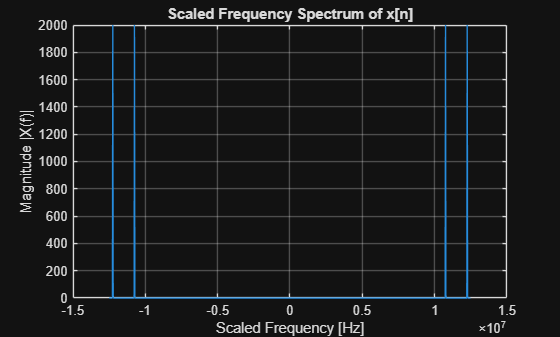



%c)
%plot the scaled (N dependent) absolute value (abs) of the spectrum as
%function of f*Fs.
scaledFreq = f * Fs; % Scale frequency by sampling frequency
figure; plot(scaledFreq, abs(X)); grid on
xlabel('Scaled Frequency [Hz]'); ylabel('Magnitude |X(f)|')
title('Scaled Frequency Spectrum of x[n]')

## Exercise 1-B

clear;
clc;
%a) Define the vectors a and b 

b = [0.398 -0.398];
a = [1 -0.6796];

x = [8; 7.6114; 6.5182; 4.9239; 3.1248; 1.4531; 0.2139; -0.3728; -0.2139; 0.6391;]

x =     8.0000
    7.6114
    6.5182
    4.9239
    3.1248
    1.4531
    0.2139
   -0.3728
   -0.2139
    0.6391




%b) calculate the discrete output signal y[n] using the filter command

y = filter(b,a,x)

y =     3.1840
    2.0092
    0.9303
   -0.0023
   -0.7176
   -1.1530
   -1.2768
   -1.1012
   -0.6851
   -0.1261


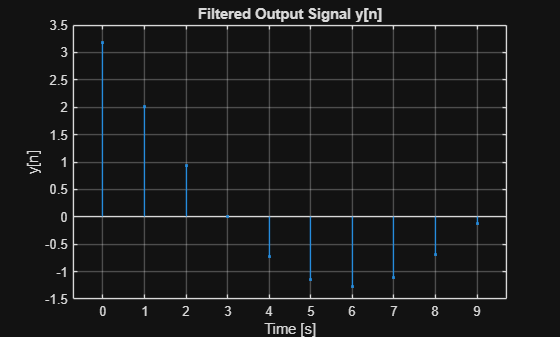


%c) plot y[n] as a stem plot as function of time.

t = 0:1:9;

figure; stem(t, y, '.'); grid on
xlabel('Time [s]'); ylabel('y[n]')
title('Filtered Output Signal y[n]');

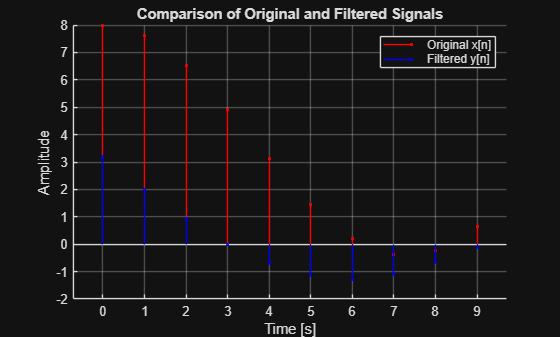


%d) Compare y[n] with x[n] and discuss what frequency component appears to have been filtered away, i.e. the low frequency component, F1, or the high frequency component, F2.

% Compare the original and filtered signals
figure; 
hold on; 
stem(t, x, 'r.', 'DisplayName', 'Original x[n]'); 
stem(t, y, 'b.', 'DisplayName', 'Filtered y[n]'); 
grid on;
xlabel('Time [s]'); 
ylabel('Amplitude');
title('Comparison of Original and Filtered Signals');
legend show;

## Exercise 1-C

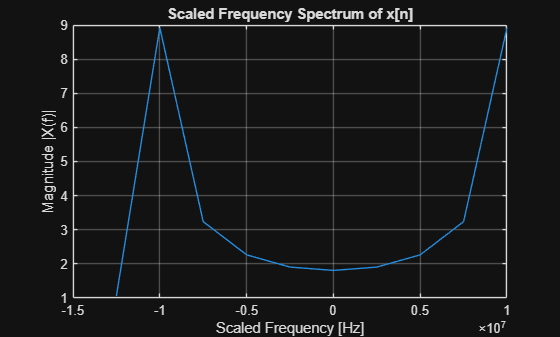

%a) Calculate the spectrum of the filtered output signal using fft and fftshift.
Y  = fft(y);            % raw FFT
Yc = fftshift(Y);       % center zero freq

%b) plot the scaled (N dependent) absolute value (abs) of the spectrum as function of f*Fs.

Fs = 5000;              % sampling frequency [Hz]
Ts = 1/Fs;              % sampling period [s]
N  = 10;              % number of samples

n = 1:N;                % sample indices
t = 0:Ts:(N-1)*Ts;    % 0, Ts, 2Ts, ..., (N-1)Ts Time vector

Df = 1/(N*Ts);
f = -Fs/2:Df:(Fs/2)-Df;

scaledFreq = f * Fs; % Scale frequency by sampling frequency
figure; plot(scaledFreq, abs(Y)); grid on
xlabel('Scaled Frequency [Hz]'); ylabel('Magnitude |X(f)|')
title('Scaled Frequency Spectrum of x[n]')